# Doppio Pendolo

Definiamo i parametri che manterremo costanti per tutta l'esercitazione:

clear;
clearvars;
m1 = 4;
m2 = 2;
l1 = 6;
l2 = 4;
g = 9.81;
dt = (0:0.05:100);
%theta1 theta2 omega1 omega2
x0 =[pi/2,0,0,0];
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Integriamo numericamente il sistema:

[t,x] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0,opts);
prima_ris = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

subplot(2,2,1);
plot(t,x(:,3));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_1$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,2);
plot(t,x(:,4));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_2$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,3);
plot(t,x(:,1));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_1}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,4);
plot(t,x(:,2));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_2}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

%exportgraphics(prima_ris,'prima_ris.eps','Resolution',300);

Scriviamo ora il sistema lineare e disaccopiamolo:

syms l t2p_1 t2p_2 g t2 t1;
eq1 = 2*l*t2p_1 + l*t2p_2 + 2*g*t1 == 0;
eq2 = l*t2p_1 +l*t2p_2 + g*t2 ==0;
sistem = [eq1,eq2];

a = isolate(eq1, t2p_2);
b = isolate(eq2, t2p_2);
eq3 = rhs(a) == rhs(b);
theta_due_punti_1 = isolate(eq3,t2p_1)

$$theta\_due\_punti\_1 = {\mathrm{t2p}}_{1}=\frac{g\,t_{2}}{l}-\frac{2\,g\,t_{1}}{l}$$



a = isolate(eq1, t2p_1);
b = isolate(eq2, t2p_1);
eq3 = rhs(a) == rhs(b);
theta_due_punti_2 = isolate(eq3,t2p_2)

$$theta\_due\_punti\_2 = {\mathrm{t2p}}_{2}=\frac{2\,g\,t_{1}-2\,g\,t_{2}}{l}$$

Possiamo ora integrarlo numericamente  con la condizione dei piccoli spostamenti:

x0 =[pi/30,0,0,0];
m_lin = m1;
l_lin = l1;

dt = (0:0.05:100);
[t,x_lin] = ode45(@(t,x)sis_lineare(t,x,m_lin,l_lin),dt,x0,opts);
sis_lin = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

subplot(2,2,1);
plot(t,x_lin(:,3));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_1$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,2);
plot(t,x_lin(:,4));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_2$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,3);
plot(t,x_lin(:,1));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_1}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

subplot(2,2,4);
plot(t,x_lin(:,2));
axis square;
xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_2}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

%exportgraphics(sis_lin,'sis_lin.eps','Resolution',300);


Andiamo ora a studiare il comportamento del sistema non lineare per piccole oscillazoni:

[t,x_non_lin] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0,opts);
sistema_non_lineare_piccolo = figure;
tilt1 = tiledlayout(4,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
nexttile;
plot(t,x_non_lin(:,3),'r');
hold on;
plot(t,x_lin(:,3),'k');
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_1$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin(:,4),'r');
hold on;
plot(t,x_lin(:,4),'k')
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_2$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin(:,1),'r');
hold on;
plot(t,x_lin(:,1),'k');

xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_1}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin(:,2),'r');
hold on;
plot(t,x_lin(:,2),'k');

xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_2}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);
tilt1.TileSpacing = 'compact';
tilt1.Padding = 'compact';

leg = legend('Non Lineare','Lineare','Orientation', 'Horizontal');
leg.Layout.Tile = 'north';
title(tilt1, 'Piccole oscillazioni');

%exportgraphics(sistema_non_lineare_piccolo ,'sistema_non_lineare_piccolo.eps','Resolution',300);

Mostriamo ora la differenza tra i due comportamenti:

differenza = figure;
til = tiledlayout(2,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
nexttile;
plot(t,abs(x_non_lin(:,3)-x_lin(:,3)));
xlabel('$t$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$|\theta_1$(lin) $-$ $\theta_1$(non lin)$|$','Interpreter','latex','FontSize',12,'FontWeight','bold');

nexttile;
plot(t,abs(x_non_lin(:,4)-x_lin(:,4)));
xlabel('$t$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$|\theta_2$(lin) $-$ $\theta_2$(non lin)$|$','Interpreter','latex','FontSize',12,'FontWeight','bold');

%exportgraphics(differenza ,'differenza.eps','Resolution',300);

Evidenziamo ora la sensibilità alle condizioni iniziali del doppio pendolo non lineare:

x0_1 = [1.56,1.56,0,0];% circa 85.9 gradi
x0_2 = [1.56 ,1.57,0,0];% circa 86.5 gradi

[t,x_non_lin_1] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0_1,opts);
[t,x_non_lin_2] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0_2,opts);

sensitivita_condizioni_iniziali = figure;
tilt2 = tiledlayout(4,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

nexttile;
plot(t,x_non_lin_1(:,3),'r');
hold on;
plot(t,x_non_lin_2(:,3),'k');
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_1$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin_1(:,4),'r');
hold on;
plot(t,x_non_lin_2(:,4),'k')
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_2$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin_1(:,1),'r');
hold on;
plot(t,x_non_lin_2(:,1),'k');

xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_1}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin_1(:,2),'r');
hold on;
plot(t,x_non_lin_2(:,2),'k');

xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_2}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);


tilt2.TileSpacing = 'compact';
tilt2.Padding = 'compact';

leg = legend('$\theta_2 = 1.50$rad','$\theta_2 = 1.51$rad','Orientation', 'Horizontal','Interpreter','latex');
leg.Layout.Tile = 'north';
title(tilt2, 'Dipendenza dalle condizioni iniziali');
%exportgraphics(sensitivita_condizioni_iniziali ,'sensitivita_condizioni_iniziali.eps','Resolution',300);

Mostrando ora la differneza:

differenza = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
tilt = tiledlayout(2,1);
nexttile;
plot(t,abs(x_non_lin_2(:,4)-x_non_lin_1(:,4)));
xlabel('$t$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$|\theta_2(1.57) - \theta_2(1.56)|$','Interpreter','latex','FontSize',12,'FontWeight','bold');
nexttile
plot(t,abs(x_non_lin_2(:,3)-x_non_lin_1(:,3)));
xlabel('$t$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$|\theta_1(1.56) - \theta_1(1.56)|$','Interpreter','latex','FontSize',12,'FontWeight','bold');

%exportgraphics(differenza ,'differenza_x0.eps','Resolution',300);

Se studiamo il sistema non lineare in regime di piccole oscillazioni:

%dt= (0:0.05:10000);
x0_1 = [pi/30,0,0,0];% circa 6 gradi
x0_2 = [pi/29,0,0,0];% circa 6.2 gradi

[t,x_non_lin_1] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0_1,opts);
[t,x_non_lin_2] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0_2,opts);
 
Piccole_oscillazioni_non_lineare = figure;
tilt2 = tiledlayout(4,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

nexttile;
plot(t,x_non_lin_1(:,1),'r');
hold on;
plot(t,x_non_lin_2(:,1),'k');
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_1$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin_1(:,2),'r');
hold on;
plot(t,x_non_lin_2(:,2),'k')
xlabel("t", 'Interpreter','latex');
ylabel("$\theta_2$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin_1(:,3),'r');
hold on;
plot(t,x_non_lin_2(:,3),'k');

xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_1}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);

nexttile;
plot(t,x_non_lin_1(:,4),'r');
hold on;
plot(t,x_non_lin_2(:,4),'k');

xlabel("t", 'Interpreter','latex');
ylabel("$\dot{\theta_2}$",'Interpreter','latex');
set(gca,'TickLabelInterpreter', 'latex','fontsize',12);


tilt2.TileSpacing = 'compact';
tilt2.Padding = 'compact';

leg = legend('$\theta_2 = 1.50$rad','$\theta_2 = 1.51$rad','Orientation', 'Horizontal','Interpreter','latex');
leg.Layout.Tile = 'north';
title(tilt2, 'Dipendenza dalle condizioni iniziali');
%exportgraphics(Piccole_oscillazioni_non_lineare ,'Piccole_oscillazioni_non_lineare.eps','Resolution',300);

Plottando ora la differenza:

differenza_piccole_oscillazioni_non_lineare = figure;
tilt = tiledlayout(2,1);
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);
nexttile;
plot(t,abs(x_non_lin_2(:,4)-x_non_lin_1(:,4)));
xlabel('$t$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$|\theta_2(0) - \theta_2(0)|$','Interpreter','latex','FontSize',12,'FontWeight','bold');
ylim([-0.4 0.4]);
nexttile;
plot(t,abs(x_non_lin_2(:,3)-x_non_lin_1(:,3)));
xlabel('$t$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$\left|\theta_1\left(\frac{\pi}{30}\right) - \theta_1\left(\frac{\pi}{29}\right)\right|$','Interpreter','latex','FontSize',12,'FontWeight','bold');
%exportgraphics(differenza_piccole_oscillazioni_non_lineare ,'Differenza_piccole_oscillazioni_non_lineare.eps','Resolution',300);

Studiamo ora la posizione della massa m1 e m2 nel piano Oxy:

x0 = [pi/3,pi/9,0,0];
[t,x] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0,opts);
%velocità e posizione massa 1
xm1 = l1*sin(x(:,3));
vxm1 = l1*cos(x(:,3)).*x(:,1);
ym1 = -l1*cos(x(:,3));
vym1 = l1*sin(x(:,3)).*x(:,1);
%velocità e posizione massa 2
xm2 = xm1 + l2.*sin(x(:,4));
vxm2 = vxm1 + l2.*cos(x(:,4)).*x(:,2);
ym2 = ym1 - l2.*cos(x(:,4));
vym2 = vym1 + l2.*sin(x(:,4)).*x(:,2);
grafico_cart= figure; 
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

tilt3 = tiledlayout(2,1);

nexttile;
plot(xm1,ym1,'r',xm2,ym2,'k');
xlabel('$x(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$y(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold');

nexttile;
plot(vxm1,vym1,'r',vxm2,vym2,'k');
xlabel('$v_x(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$v_y(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold');
tilt3.TileSpacing = 'compact';
tilt3.Padding = 'compact';

leg = legend('m1','m2','Orientation', 'Horizontal','Interpreter','latex');
leg.Layout.Tile = 'north';
title(tilt3, 'Traiettorie nel piano cartesiano');
%exportgraphics(grafico_cart ,'grafico_cart.eps','Resolution',300);

In regime di piccole oscillazioni:

x0 = [pi/30,pi/30,0,0];
[t,x] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0,opts);
%velocità e posizione massa 1
xm1 = l1*sin(x(:,3));
vxm1 = l1*cos(x(:,3)).*x(:,1);
ym1 = -l1*cos(x(:,3));
vym1 = l1*sin(x(:,3)).*x(:,1);
%velocità e posizione massa 2
xm2 = xm1 + l2.*sin(x(:,4));
vxm2 = vxm1 + l2.*cos(x(:,4)).*x(:,2);
ym2 = ym1 - l2.*cos(x(:,4));
vym2 = vym1 + l2.*sin(x(:,4)).*x(:,2);
grafico_cart_piccole = figure; 
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

tilt3 = tiledlayout(2,1);

nexttile;
plot(xm1,ym1,'r',xm2,ym2,'k');
xlabel('$x(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$y(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold');

nexttile;
plot(vxm1,vym1,'r',vxm2,vym2,'k');
xlabel('$v_x(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold'); 
ylabel('$v_y(t)$','Interpreter','latex','FontSize',12,'FontWeight','bold');
tilt3.TileSpacing = 'compact';
tilt3.Padding = 'compact';

leg = legend('m1','m2','Orientation', 'Horizontal','Interpreter','latex');
leg.Layout.Tile = 'north';
title(tilt3, 'Traiettorie nel piano cartesiano');
%exportgraphics(grafico_cart_piccole ,'grafico_cart_piccole.eps','Resolution',300);

Disegnamo lo spazio delle fasi come toroide:

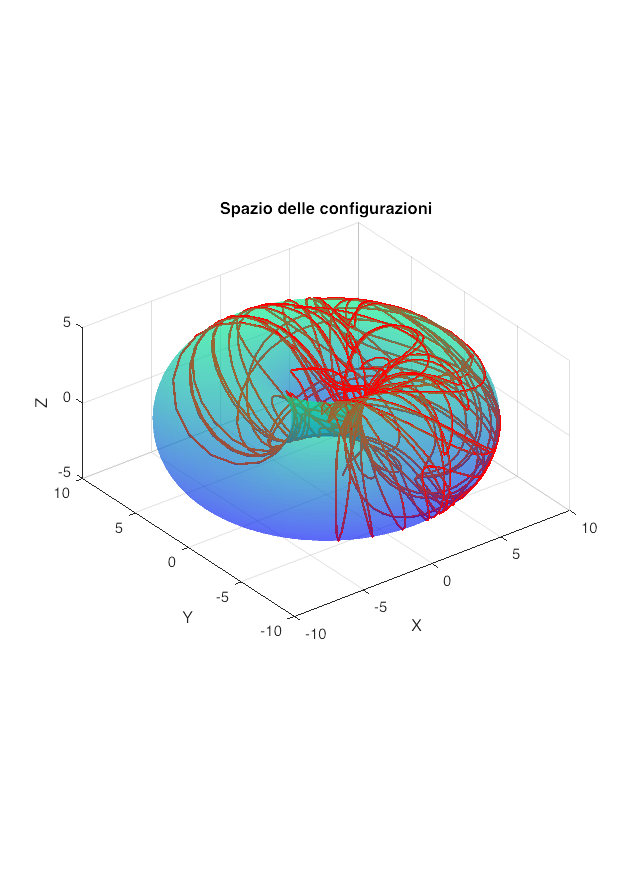

toro = figure;
set(gcf,'PaperUnits','centimeters');
set(gcf,'Position',[100,100,420,580]);

R = l1;
r=l2; 
th=linspace(0,2*pi,100); 
phi=linspace(0,2*pi,100); 
[Phi,Th]=meshgrid(phi,th); 
x=(R+r.*cos(Th)).*cos(Phi);
y=(R+r.*cos(Th)).*sin(Phi);
z=r.*sin(Th);
surf(x,y,z); 
daspect([1 1 1])
colormap('winter');
shading flat;
alpha(.4);
title('Spazio delle configurazioni');
xlabel('X');
ylabel('Y');
zlabel('Z');



hold on;
x0 = [pi/3,pi/3,0,0];
[t,x] = ode45(@(t,x)sis_non_lineare(x,t,m1,m2,l1,l2),dt,x0,opts);
xm2 = (R+r.*cos(x(:,4))).*cos(x(:,3));
ym2 = (R+r.*cos(x(:,4))).*sin(x(:,3));
zm2 = (r.*sin(x(:,4)));
plot3(xm2,ym2,zm2,'r','LineWidth',1.5);
exportgraphics(toro ,'toro.eps','Resolution',300);